### General setup

Clear the workspace:

clear; close all

Get the proximity graphs toolbox on your path: this will be different for you:

addpath("ProximityGraphs\");

I want this code to have reproducible results - so I am going to reset the seed for the random number generator.

rng(0);

Build the beta skeleton network - NB adapted from some stuff I already showed you:

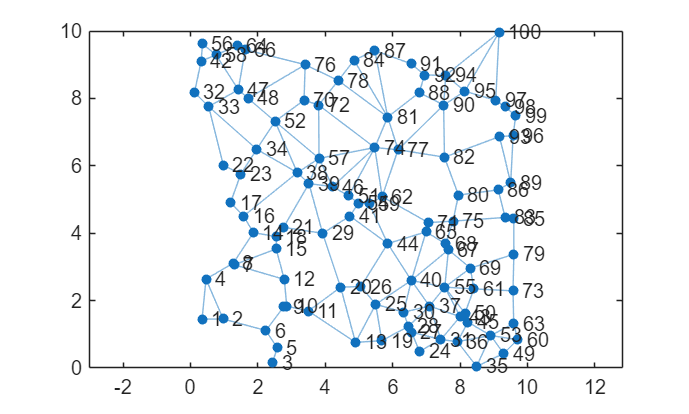

L=10; % side of square - let's just say its kilometres
numNode = 100;
nodeCoordinates = L*rand(numNode,2);
[~,inds]=sort(sum(nodeCoordinates')');
nodeCoordinates=nodeCoordinates(inds,:);
distanceMatrix = squareform(pdist(nodeCoordinates));
beta=0; % documentation says this is the Gabriel graph - caution with defn of beta
cbsg = CircleBetaSkeletonGraph(nodeCoordinates,distanceMatrix,beta);
A=cell2mat(cbsg);
G = graph(A.*distanceMatrix);
% the second bit is just naming the nodes 1,2,3 etc.
plot(G,'XData',nodeCoordinates(:,1),'YData',nodeCoordinates(:,2),'NodeLabelMode','auto')
axis([0 L 0 L])
axis equal

I have nearly the complete set-up. G is storing the graph structure, and the edge weights in it are recording the lengths of links. For plotting I need to hold on to nodecoordinates. Most of the other stuff can be cleared out of memory at this point.

clear beta cbsg inds distanceMatrix A

I need to allocate affine costs for each edge. NB this is a "for example" - other choices are possible for a and b. For example, different streets having different speeds would lead to different a. Also, this becomes much more interesting if the streets have different congestibility.

numEdge = height(G.Edges);
a=G.Edges.Weight; % take free flow travel cost to be length of the link.
b=ones(numEdge,1); % set the congestibility of each street to be the same.

Now I am going to specifiy an origin and a destination node

oNode=1; % the bottom LH corner
dNode=100; % the top RH corner

So the network problem at this point is specified by variables now in memory: G, a, b, dNode, and oNode - and the other variables L, nodeCoordinates, numEdge, numNode are useful things to keep around also. You can set up any graph you like and provided you compute these variables in a way consistent to how I have done above - the code below that builds the assignment problems should work.

In case you can't get the proximity graph toolbox to work - let's save the data that comes out of this so that I can give you a copy of what I have done.

save BigNetworkExperimentsBetaSkeleton.mat

Let's just suppose you want load in the pre-prepared data

clear; close all
load BigNetworkExperimentsBetaSkeleton.mat

### Building the node constraints

The number of routes from node 1 to 100 is erm rather large. So we definitely aren't going to compute them all and so route variables (flows) is not the way to go here. 

% paths=allpaths(G,oNode,dNode);  
% don't execute this code unless you want
% your computer to hang

You could of course compute an assignment using just a small subset of the available routes - and that is what you need to do in SUE problems - but here, for classical UE, a tractable approach is instead to use the link-based formulation and the Beckmann functional, which will lead to a quadratic programme with linear constraints. The SO problem is very similar, with just a slight change to the function that must be minimised.

There are numEdge links and therefore the link flow vector $\mathbf{x}$ that we try to solve for is of length numEdge. The node constraints are $\mathbf{B}\mathbf{x}=\mathbf{s}$, as explained in lectures, and we need to formulate the $\mathbf{B}$ and the $\mathbf{s}$. 

In fact, $\mathbf{s}$ is rather easy.

s = zeros(numNode,1);
s(oNode)=1;
s(dNode)=-1;

This expresses that for most nodes, the corresponding element of $\mathbf{s}$ is zero, ie traffic is conserved, whereas at O it is generated at rate 1 and at D it is absorbed at rate 1. We can then scale $\mathbf{s}$ by a scalar demand parameter $d$ a bit later on.

The matrix $\mathbf{B}$ is then built up node by node by considering which edges point out (+1) and point in (-1). To be honest, it doesn't matter which way round you do the signs provided you correct $\mathbf{s}$ accordingly.

B=zeros(numNode,numEdge);
listEdge = [1:numEdge]';
sNode = G.Edges.EndNodes(:,1);
tNode = G.Edges.EndNodes(:,2);
isCleverMethod= false;
if isCleverMethod
% I think there is a vectorised way of doing this if only I were clever
else % do it ponderously with a loop
    for i=1:numEdge
        B(sNode(i),listEdge(i))=1;
        B(tNode(i),listEdge(i))=-1;
    end
end

### Constructing the objective and running the quadratic programme

d=0.001; % set the demand - no idea if this is a good value

Take a look at help page for quadprog - we will use the form

 X = quadprog(H,f,A,b,Aeq,beq,LB,UB)

First the constraints

Aeq=B;     % node conservation matrix
beq=d*s;   % node conservation vector
A=[];      % no inequality constraints
bvec=[];      % no inequality constraints - note avoiding name conflict with my existing b
LB = zeros(numEdge,1); % set a lower bound of zero for all of the link flows.
UB=[]; % no upper bounds for the link flows - although you could use this facility to set
% a capacity (ie max flow) for each link

Now set up the objective function

H=diag(b); % the square matrix with the elements of b on its diagonal.
% Note this is what is needed for the Beckmann functional, because of the
% way matlab inserts a factor of 1/2 in front of the quadratic form.
% If we were doing SO, there would need to be a factor of 2 in here.

f=a; % the linear part of the quadratic form

We are ready to rock.

tic;
[x,fval,exitflag]=quadprog(H,f,A,bvec,Aeq,beq,LB,UB);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc;

Elapsed time is 0.044411 seconds.


Hey presto - x contains the UE link flows. Inspect it. Notice there are some unused links.

fval contains the minimum value of the Beckmann functional - note this is no the system cost, rather that is

a'*x + x'*H*x

ans =    0.013541904563840
